clear all
clc

% 
% Homework 3 - Problem 1
% Student Name: Giuditta Sigona
% Created on 21/05/2022
% Last version 29/05/2022


% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;


% SISO plant
G =zpk(s/(s+4)^2) 

G =
 
     s
  -------
  (s+4)^2
 
Continuous-time zero/pole/gain model.



% Controller
C = zpk(10/(s+10))

C =
 
    10
  ------
  (s+10)
 
Continuous-time zero/pole/gain model.




%% inputs and outputs
C.y='m';
C.u='a';
G.y='c';
G.u='m';

% sumblk interconnections
sum1=sumblk('y = c + d2');
sum2=sumblk('b = n + y');
sum3=sumblk('a = r - b');
sum4=sumblk('ey = r - y');


%case 1: Considering r and n as inputs, y and m as outputs and setting all
%the other inputs to 0.

% augmented plant
Pe1=connect(C,G,sum3,sum2,sum1,{'r','n'},{'y','m'});

Pe1=tf(Pe1)

Pe1 =
 
  From input "r" to output...
            10 s - 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          10 s^2 + 80 s + 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
  From input "n" to output...
           -10 s + 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          -10 s^2 - 80 s - 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
Continuous-time transfer function.




%check if it is A.S.
isstable(Pe1)

ans = logical
   1


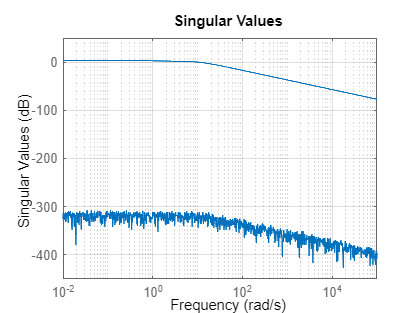


%plot the singular values of the frequency response of the system
% the singular value plot shows min(Nu,Ny) lines on the plot corresponding to each singular value of the frequency response matrix.
sigma(Pe1,om),grid


Pe1_0=dcgain(Pe1)

Pe1_0 =    -0.0000    0.0000
    1.0000   -1.0000


% performs a singular value decomposition of matrix Pe1_0 = U*S*V'.
[U1,S1,V1]= svd(Pe1_0)

U1 =      0     1
     1     0


S1 =     1.4142         0
         0         0


V1 =     0.7071    0.7071
   -0.7071    0.7071


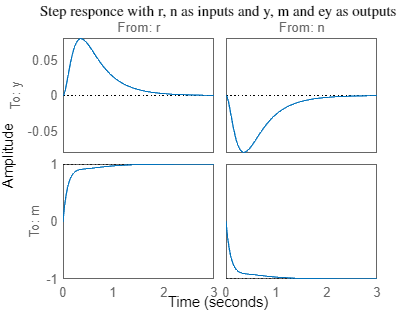

step(Pe1)
title('Step responce with r, n as inputs and y, m and ey as outputs','Interpreter','latex')

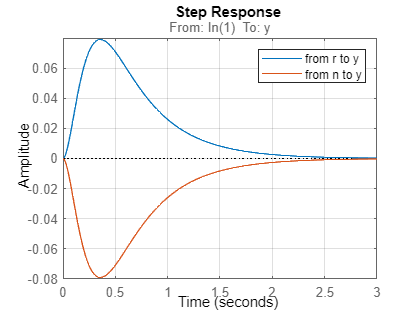


%we know the Maximum value of σ is obtained when the input is along the v1
%direction. Instead, the smallest value σ is obtained if the input is in the
%v2 direction

step(Pe1(1,1),Pe1(1,2));
grid on;
legend('from r to y','from n to y')

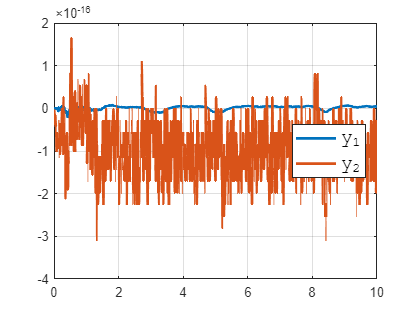


%apply a input w = v1*step
w = V1(:,2)*stepfun(t,0);  %--> the output at ss should goes to 0
Y1 = lsim(Pe1,w,t);
plot(t,Y1(:,1),t,Y1(:,2),'LineWidth',2), grid
legend('y_1','y_2','Location','East','FontSize',14,'Fontname','Courier')



%apply a step input
t = 0:0.01:10;
ra = [stepfun(t,0);0*t]

ra =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


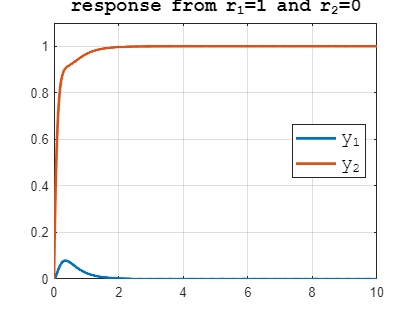

Yc = lsim(Pe1,ra,t);
plot(t,Yc(:,1),t,Yc(:,2),'LineWidth',2), grid
axis([0,10,0,1.1])
legend('y_1','y_2','Location','East','FontSize',14,'Fontname','Courier')
title('response from r_1=1 and r_2=0',...
    'FontSize',14,'Fontname','Courier')


%  goes to 1 and  goes to 0 (they both "follow" the reference)


%case 2: Keeping the same inputs r and n, add ey as output.

% augmented plant
Pe2=connect(C,G,sum3,sum2,sum1,sum4,{'r','n'},{'y','m','ey'});

Pe2=tf(Pe2)

Pe2 =
 
  From input "r" to output...
            10 s - 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          10 s^2 + 80 s + 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
        s^3 + 18 s^2 + 96 s + 160
   ey:  --------------------------
        s^3 + 18 s^2 + 106 s + 160
 
  From input "n" to output...
           -10 s + 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          -10 s^2 - 80 s - 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
             10 s - 1.256e-14
   ey:  --------------------------
        s^3 + 18 s^2 + 106 s + 160
 
Continuous-time transfer function.




%check if it is A.S.
isstable(Pe2)

ans = logical
   1


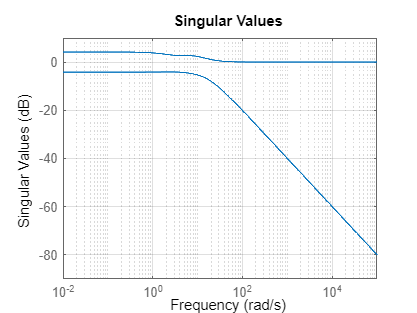


sigma(Pe2,om),grid

Pe2_0=dcgain(Pe2)

Pe2_0 =    -0.0000    0.0000
    1.0000   -1.0000
    1.0000   -0.0000


% performs a singular value decomposition of matrix Pe1_0 = U*S*V'.
[U2,S2,V2]= svd(Pe2_0)

U2 =          0         0    1.0000
    0.8507   -0.5257    0.0000
    0.5257    0.8507         0


S2 =     1.6180         0
         0    0.6180
         0         0


V2 =     0.8507    0.5257
   -0.5257    0.8507


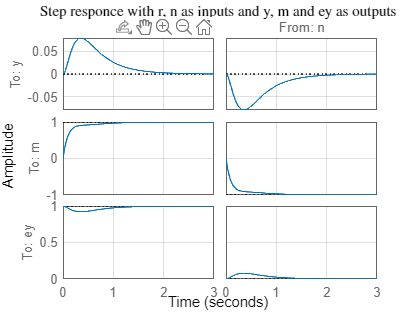

step(Pe2),grid
title('Step responce with r, n as inputs and y, m and ey as outputs','Interpreter','latex')

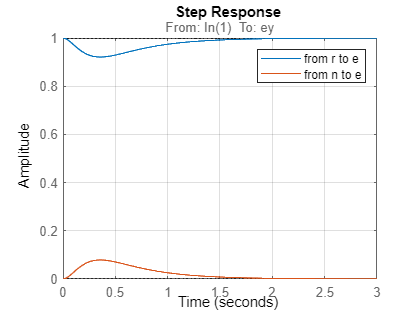


step(Pe2(3,1),Pe2(3,2));
grid on;
legend('from r to e','from n to e')

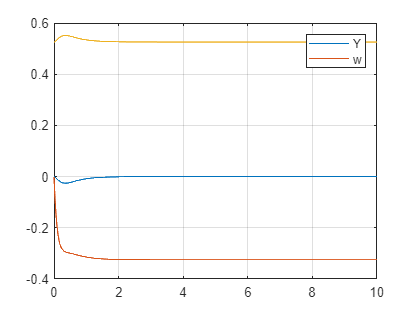


%apply a input w = v1*step
w = V2(:,2)*stepfun(t,0);  %--> the output at ss should goes to 0
Y2 = lsim(Pe2,w,t);
plot(t,Y2),grid
legend('Y','w')

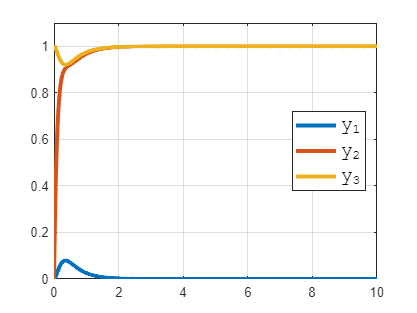


%apply a step input
t = 0:0.01:10;
ra = [stepfun(t,0);0*t];
Yc2 = lsim(Pe2,ra,t);
plot(t,Yc2(:,1),t,Yc2(:,2),t,Yc2(:,3),'LineWidth',2), grid
axis([0,10,0,1.1])
legend('y_1','y_2','y_3','Location','East','FontSize',14,'Fontname','Courier')

%case 3: keeping the outputs y and m, add d2 as input

% augmented plant
Pe3=connect(C,G,sum3,sum2,sum1,{'r','n','d2'},{'y','m'});
Pe3=tf(Pe3)

Pe3 =
 
  From input "r" to output...
            10 s - 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          10 s^2 + 80 s + 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
  From input "n" to output...
           -10 s + 1.256e-14
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          -10 s^2 - 80 s - 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
  From input "d2" to output...
       s^3 + 18 s^2 + 96 s + 160
   y:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
          -10 s^2 - 80 s - 160
   m:  --------------------------
       s^3 + 18 s^2 + 106 s + 160
 
Continuous-time transfer function.




%check if it is A.S.
isstable(Pe3)

ans = logical
   1


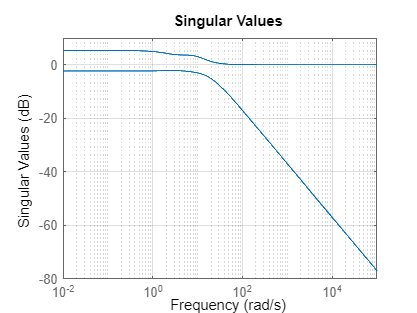


sigma(Pe3,om),grid

Pe3_0=dcgain(Pe3)

Pe3_0 =    -0.0000    0.0000    1.0000
    1.0000   -1.0000   -1.0000


% performs a singular value decomposition of matrix Pe1_0 = U*S*V'.
[U3,S3,V3]= svd(Pe3_0)

U3 =    -0.3827   -0.9239
    0.9239   -0.3827


S3 =     1.8478         0         0
         0    0.7654         0


V3 =     0.5000   -0.5000    0.7071
   -0.5000    0.5000    0.7071
   -0.7071   -0.7071   -0.0000


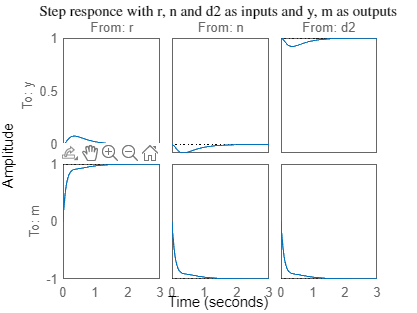

step(Pe3)
title('Step responce with r, n and d2 as inputs and y, m as outputs','Interpreter','latex')

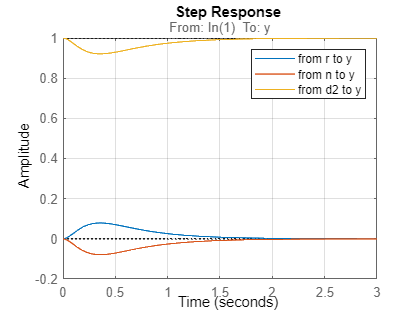


step(Pe3(1,1),Pe3(1,2),Pe3(1,3));
grid on;
legend('from r to y','from n to y', 'from d2 to y')

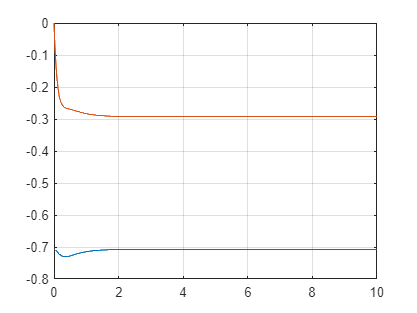


%apply a input w = v1*step
w = V3(:,2)*stepfun(t,0);  %--> the output at ss should goes to 0
Y3 = lsim(Pe3,w,t);
plot(t,Y3),grid

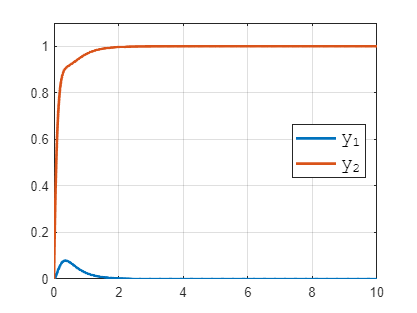


%apply a step input
t = 0:0.01:10;
ra = [stepfun(t,0);0*t;0*t];
Yc3 = lsim(Pe3,ra,t);
plot(t,Yc3,'LineWidth',2), grid
axis([0,10,0,1.1])
legend('y_1','y_2','Location','East','FontSize',14,'Fontname','Courier')

%Problem 1 - case 4
%add a weight
wB1=0.4

wB1 = 0.4000

Ms1=2

Ms1 = 2

A1=0.01

A1 = 0.0100

ws1=(s/Ms1+wB1)/(s+wB1*A1) % performance weight; |1/ws|:performance bound

ws1 =
 
    s + 0.8
  -----------
  2 s + 0.008
 
Continuous-time transfer function.




[MagWs1,PhaseWs1]=bode(ws1,om);

wB2=0.2

wB2 = 0.2000

Ms2=2

Ms2 = 2

A2=0.01

A2 = 0.0100

ws2=(s/Ms2+wB2)/(s+wB2*A2) % performance weight; |1/ws|:performance bound

ws2 =
 
    s + 0.4
  -----------
  2 s + 0.004
 
Continuous-time transfer function.



[MagWs2,PhaseWs2]=bode(ws2,om);

[Cont2,CL2,Gamma2]=mixsyn(Pe1,[ws1 0; 0 ws2],[],[]); %controller Hinf

SF2=loopsens(Pe1,Cont2)

SF2 = struct with fields:
        Si: [2×2 ss]
        Ti: [2×2 ss]
        Li: [2×2 ss]
        So: [2×2 ss]
        To: [2×2 ss]
        Lo: [2×2 ss]
       PSi: [2×2 ss]
       CSo: [2×2 ss]
     Poles: [14×1 double]
    Stable: 1


Gamma2

Gamma2 = 100.0000

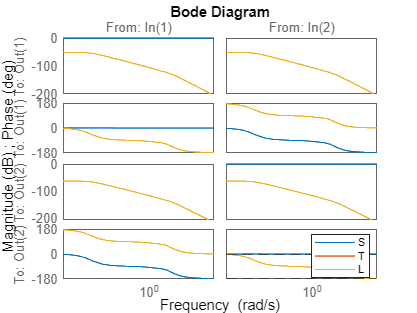


bode(SF2.Si,SF2.Ti,SF2.Li)
yline(0,'--')
yline(-180,'--')
legA = legend('S','T','L','Location','SouthEast');
set(legA,'FontSize',8)

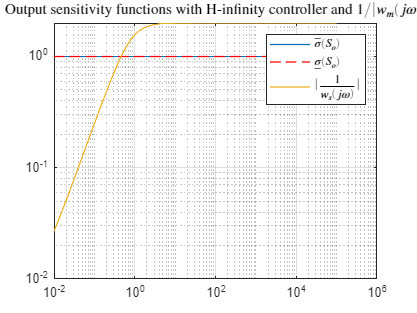


% check performance
So2=SF2.So;

SVSo2=sigma(So2,om);
loglog(om,SVSo2(1,:),om,SVSo2(2,:),'r--',om,1./MagWs1(:),'LineWidth',1),grid
Tit1=title('Output sensitivity functions with H-infinity controller and $1/|w_m(j\omega)|$','Interpreter','latex');
legend('$\bar\sigma(S_o)$','$\underline\sigma(S_o)$','$|\frac{1}{w_s(j\omega)}|$','Interpreter','Latex')

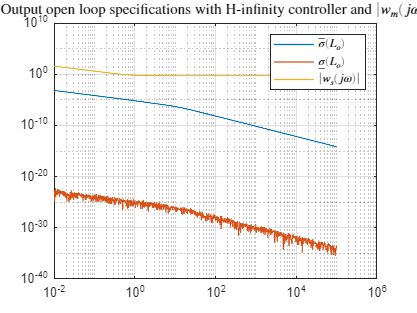


Lo2=SF2.Lo;

SVLo2=sigma(Lo2,om);
loglog(om,SVLo2(1,:),om,SVLo2(2,:),om,MagWs1(:),'LineWidth',1),grid
Tit1=title('Output open loop specifications with H-infinity controller and $|w_m(j\omega)|$','Interpreter','latex');
legend('$\bar\sigma(L_o)$','$\underline\sigma(L_o)$','$|w_s(j\omega)|$','Interpreter','Latex')

t = 0:0.01:10;
isstable(Pe1*Cont2) %stable

ans = logical
   1


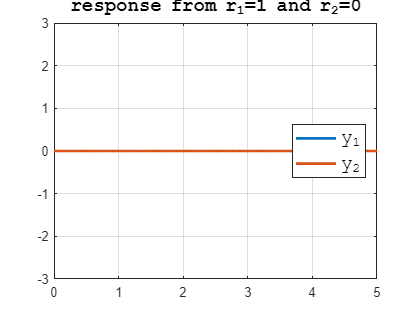

ra = [stepfun(t,0);0*t];

Yc = lsim(feedback(Pe1*Cont2,eye(2)),ra,t);
plot(t,Yc(:,1),t,Yc(:,2),'LineWidth',2), grid
axis([0,5,-3,3])
legend('y_1','y_2','Location','East','FontSize',14,'Fontname','Courier')
title('response from r_1=1 and r_2=0',...
    'FontSize',14,'Fontname','Courier')



%try to use another controller
Kc = [1*(s+1)/s,0;0,2*(s+1)/s];
isstable(Pe1*Kc) %unstable

ans = logical
   0


Yc1 = lsim(feedback(Pe1*Kc,eye(2)),ra,t);
plot(t,Yc(:,1),t,Yc(:,2),'LineWidth',2), grid
axis([0,5,-3,3])
legend('y_1','y_2','Location','East','FontSize',14,'Fontname','Courier')
title('response from r_1=1 and r_2=0',...
    'FontSize',14,'Fontname','Courier')



%try to use another controller with higher values on the gain --> unstable
%If we try to get a faster transient by choosing higher values of the gains  and , the closed loop system becomes unstable
Kd = [4*(s+1)/s,0;0,12*(s+1)/s]
isstable(Pe1*Kd)  %unstable

ans = logical
   0


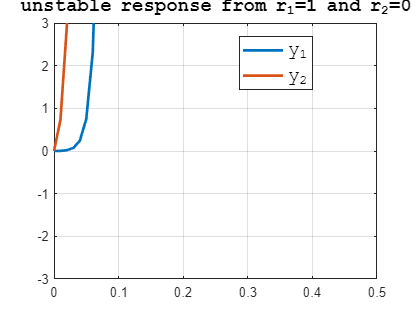

Yd = lsim(feedback(Pe1*Kd,eye(2)),ra,t);
plot(t,Yd(:,1),t,Yd(:,2),'LineWidth',2), grid
axis([0,0.5,-3,3])
legend('y_1','y_2','Location','NorthWest','FontSize',14,'Fontname','Courier')
title('unstable response from r_1=1 and r_2=0',...
    'FontSize',14,'Fontname','Courier')